# Inference of Model

## Load and import dataset

clear all; load('./data/dc_corr.mat','dc'); addpath('./functions/'); load('coastlines.mat'); warning('off')
load('./data/BelowRadarMPS.mat');
Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );

## Convert the data to a simple structure

Define the `data` structure with all data.

data.name = {dc.name}';
data.lat = [dc.lat]';
data.lon = [dc.lon]';
data.height = [dc.height]';
data.heightDEM = [dc.heightDEM]';
data.maxrange = [dc.maxrange]';
data.nrad = numel(data.name);
data.time = dc(1).time';
data.alt = dc(1).alt';
data.NNT = datenum(repmat(data.time,1,numel(dc))-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;

Initiate empty density matrix

data_denss_sim = nan(numel(data.time),  numel(dc), size(MPS{1},3));

Loop for eac radar

for i_d=1:numel(dc)
    % Vertical agregation accounts for the DEM based on VolBelow.
    % First, find the direction of flight of the lowest non-nan bin
    [~, id]  = max(~isnan(dc(i_d).dd), [], 2);
    dir_lowest = dc(i_d).dd(sub2ind(size(dc(i_d).dd), (1:numel(data.time))',id));
    % Transform this direction angle (0-360°) into the index of alpha (-90°-90°)
    dir_lowest_round = round(dir_lowest,-1);
    id_alpha=nan(size(dir_lowest_round));
    id_alpha(dir_lowest_round>=0 & dir_lowest_round<90) = dir_lowest_round(dir_lowest_round>=0 & dir_lowest_round<90)+90;
    id_alpha(dir_lowest_round>=90 & dir_lowest_round<270) = dir_lowest_round(dir_lowest_round>=90 & dir_lowest_round<270)-90;
    id_alpha(dir_lowest_round>=270 & dir_lowest_round<360) = dir_lowest_round(dir_lowest_round>=270 & dir_lowest_round<360)-270;
    id_alpha = id_alpha/10+1;
    height_vol = nan(numel(data.time),numel(data.alt));
    height_vol(~isnan(id_alpha),:) = dc(i_d).VolBelow(id_alpha(~isnan(id_alpha)),:);
    
    % Integrate volume density into surface density based on the direction and corresponding volume. bird/km^2
    % data.denss(:,i_d) = sum(data_dens(:,:,i_d) .* height_vol,2);
    
    % Computing with result of MPS
    tmp = dc(i_d).dens4;
    data_denss_MPS = nan(size(tmp,1),size(MPS{i_d},3),size(tmp,2));
    for i_real=1:size(MPS{i_d},3)
        tmp(:,1:dc(i_d).scatter_lim-1) = MPS{i_d}(:,1:dc(i_d).scatter_lim-1,i_real);
        data_denss_MPS(:,i_real,:) = tmp .* height_vol;
    end
    data_denss_sim(:,i_d,:) = sum(data_denss_MPS,3);
    
    % Compute speed
    nb_bird = permute(nanmean(data_denss_MPS,2),[1 3 2]);
    w_MTR = nb_bird ./ repmat(nansum(nb_bird,2),1,size(nb_bird,2));
    
    data.vs(:,i_d) = nansum(w_MTR .* dc(i_d).v2,2);
    data.us(:,i_d) = nansum(w_MTR .* dc(i_d).u2,2);
    
    % if data present initially
    data.isdata(:,i_d)=~all(isnan(dc(i_d).DBZH),2);
end
data.vs(data.vs==0)=nan;
data.us(data.us==0)=nan;

Set  data during the day to zero

data_denss_sim(repmat((data.NNT<-1 | data.NNT>1),1,1,size(data_denss_sim,3)))=nan;
data.vs(data.NNT<-1 | data.NNT>1)=nan;
data.us(data.NNT<-1 | data.NNT>1)=nan;

Remove 0 value because of the transformation

data_denss_sim(data_denss_sim==0)=nan;

Remove data when there is only a few data point (8 => 2h00) per day

tmp=dateshift(data.time,'start','day','nearest');
day_id=findgroups(datenum(tmp));
G = findgroups(day_id);
nb = splitapply(@nansum,~isnan(data_denss_sim),G);
data_denss_sim(nb(day_id,:,:)<8)=nan;

Remove time with all day or no data to save space

data.id_t=all(all(isnan(data_denss_sim),2),3);
data.time(data.id_t)=[];
data.ntime = numel(data.time);
data.NNT(data.id_t,:)=[];
data_denss_sim(data.id_t,:,:)=[];
data.vs(data.id_t,:)=[];
data.us(data.id_t,:)=[];
data.isdata(data.id_t,:)=[];
tmp=dateshift(data.time,'start','day','nearest');
[data.day_id,data.day]=findgroups(datenum(tmp));
G = findgroups(data.day_id);
nb = splitapply(@nansum,~isnan(data_denss_sim),G);

Clear variable to make space (if necessary)

clear id_t tmp1 dens_lim tmp w_MTR nb_bird data_u data_v ff dd data_dens dir_lowest dir_lowest_round height_vol id_alpha id i_d dir i_real data_denss_MPS MPS

## Rain

Determine the threashold

file='./ECMWF/2018_srf.nc'; %ncdisp(file);
rain.time = datenum('01-janv-2018'):1/24:datenum('31-dec-2018 23:00');
rain.latitude=flip(double(ncread(file,'latitude')));
rain.longitude=double(ncread(file,'longitude'));
rain.tp = permute(flip(ncread(file,'tp'),2) , [2 1 3]); % Total precipitation [m] (accumulation over the hour ending at the forcast step)

F = griddedInterpolant({rain.latitude,rain.longitude,datenum(rain.time)},rain.tp);
for i_d=1:numel(dc)
    data.rain(:,i_d) = F({data.lat(i_d),data.lon(i_d),datenum(data.time)});
end

Consider only night time, where data is present (i.e. DBZH available)

consider = data.NNT>-1 & data.NNT<1 & data.isdata;

Bird density

tmp = data_denss_sim(:,:,1);

Figure to illustrate

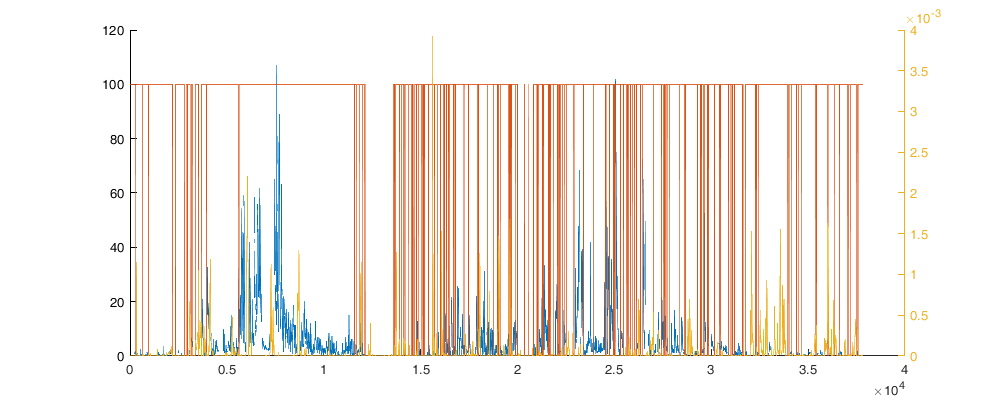

% figure; hold on;
% histogram(data.rain(isnan(tmp)&consider))
% histogram(data.rain(~isnan(tmp)&consider))
% set(gca,'YScale','log')

% figure; scatter(data.rain(consider), tmp(consider),'k.')

figure('position',[0 0 1000 400]); hold on;
plot(tmp(:,2))
plot(data.isdata(:,2)*100)
yyaxis right; 
plot(data.rain(:,2))

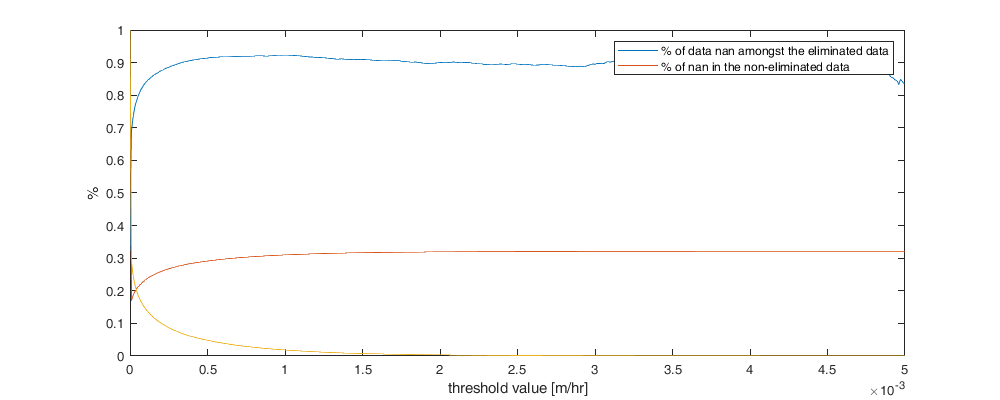


thr=0:0.00001:0.005;
score=nan(3,numel(thr));
for i=1:numel(thr)
    rain_id=data.rain>=thr(i);
    score(1,i)=mean(isnan(tmp(rain_id&consider)));
    score(2,i)=mean(isnan(tmp(~rain_id&consider)));
    score(3,i)=sum(rain_id(:)&consider(:))/sum(consider(:));
end
figure('position',[0 0 1000 400]); plot(thr,score'); xlabel('threshold value [m/hr]'); ylabel('%')
legend('% of data nan amongst the eliminated data','% of nan in the non-eliminated data')

This threashold value is defined at 1 mm/hr -> 0.001 m at the hourly resolution of the total precipitation according to [https://confluence.ecmwf.int//display/CKB/ERA5+data+documentation#ERA5datadocumentation-Meanratesandaccumulations](https://confluence.ecmwf.int//display/CKB/ERA5+data+documentation#ERA5datadocumentation-Meanratesandaccumulations)

data.mask_rain_thr=0.001;

Clear variable

clear rain F file consider tmp score

## Transformation of data

Raw data very skew, transformation to normal space using a kernel-based density fit. 

Transformation does not work for dens=0. remove for the fit

pd=fitdist(data_denss_sim(:),'Kernel','Support','positive');

Too many data for the forward transformation. Reduce the site of the data to transform using only the value rounded to 2 decimal. Compute the transformation of the MPS simulation and compute the std

trans.dens_axis = logspace(log10(min(data_denss_sim(:))), log10(max(data_denss_sim(:))),1000);
trans.denst_axis = norminv(cdf(pd,trans.dens_axis));
trans.dens_axis([false diff(trans.denst_axis)==0])=[];
trans.denst_axis([false diff(trans.denst_axis)==0])=[];
data.denst = interp1(trans.dens_axis,trans.denst_axis,data_denss_sim,'pchip');
data.denst_m = nanmean(data.denst,3);
% data.denst_s = nanstd(data.denst,[],3);

inverse: SUPER SLOW

% data.dens_m = icdf(pd,normcdf(data.denst_m));
data.dens_m = interp1(trans.denst_axis,trans.dens_axis,data.denst_m,'pchip');

Figure

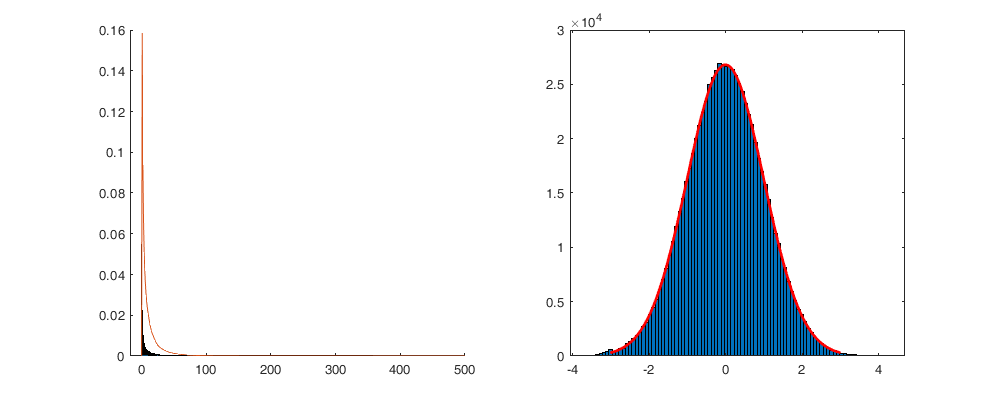

figure('position',[0 0 1000 400]); hold on;
subplot(1,2,1); hold on;
histogram(data_denss_sim(:),'Normalization','probability'); plot(0:500,pdf(pd,0:500))
tmp = nanmean(data.denst,3);
subplot(1,2,2); histfit(tmp(:),100)

clear pd

## Block decompostion

We compute the parameters of the trends and covariance function on each temporal subset (=block) of the dataset. Each block of the dataset is of size `data_block` days and add some overlap with previous and next day of `block_overlap` days.

data.block.date = [737121 737184 737273 737384]; % '13-Feb-2018', '02-Mar-2018', '23-Apr-2018','24-Sep-2018', '20-Nov-2018', '01-Jan-2019'
data.block.date_str={'Spring (02-Mar  - 04-May)','Summer (4-May - 1-Aug)','Autumn (1-Aug - 20-Nov)','Winter (20-Nov - 02-Mar)'};
data.block.col = [[81 161 114];[206 202 105];[213 122 93];[85 126 170]]/255;

These date are defined with the figure below

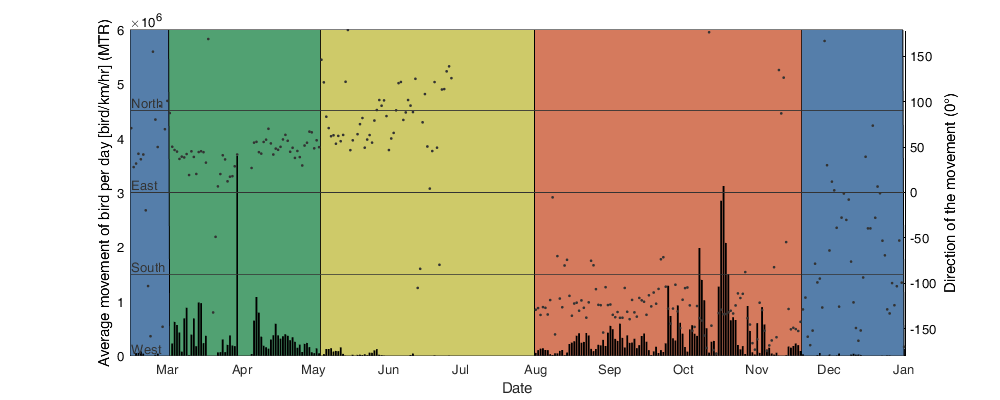

U=nanmean(splitapply(@nanmean, (data.us*60*60/1000.*data.dens_m), data.day_id),2);
V=nanmean(splitapply(@nanmean, (data.vs*60*60/1000.*data.dens_m), data.day_id),2);
MTR = sqrt(U.^2+V.^2);

figure('position',[0 0 1000 400]); hold on
% Background color
for i_b=1:numel(data.block.date)-1
    fill([data.block.date(i_b)-.5 data.block.date(i_b)-.5 data.block.date(i_b+1)-.5 data.block.date(i_b+1)-.5],[4.5 0 0 4.5]*1000,data.block.col(i_b,:))
end
fill([min(data.day)-.5 min(data.day)-.5 data.block.date(1) data.block.date(1)-.5],[4.5 0 0 4.5]*1000,data.block.col(4,:))
fill([data.block.date(end)-.5 data.block.date(end)-.5 max(data.day) max(data.day)-.5],[4.5 0 0 4.5]*1000,data.block.col(4,:))
% MTR
bar(data.day,MTR,'k')
ylabel('Average movement of bird per day [bird/km/hr] (MTR)');
% MTR direction
yyaxis right; plot(data.day,atan2d(V,U),'.','Color',[.2 .2 .2]);
ylabel('Direction of the movement (0°)');
line([data.day(1) data.day(end)],[0 0],'Color',[.2 .2 .2]); text(data.day(1),8,'East','Color',[.2 .2 .2])
line([data.day(1) data.day(end)],[90 90],'Color',[.2 .2 .2]); text(data.day(1),98,'North','Color',[.2 .2 .2])
line([data.day(1) data.day(end)],[-180 -180],'Color',[.2 .2 .2]); text(data.day(1),-172,'West','Color',[.2 .2 .2])
line([data.day(1) data.day(end)],[-90 -90],'Color',[.2 .2 .2]); text(data.day(1),-82,'South','Color',[.2 .2 .2])
ylim([-180 180]);
datetick('x'); xlabel('Date'); ax = gca;ax.YAxis(1).Color = 'k';ax.YAxis(2).Color = 'k'; axis tight;

for i_b=1:numel(data.block.date)
    if i_b==numel(data.block.date)
        data.b(datenum(data.time)>=data.block.date(4) | datenum(data.time)<data.block.date(1)) = i_b;
    else
        data.b(datenum(data.time)>=data.block.date(i_b) & datenum(data.time)<data.block.date(i_b+1)) = i_b;
    end
end

## Average Daily

Compute the radar and day index (t and r)

multi.t = data.day;
multi.r = 1:data.nrad;
[multi.R,multi.T]=meshgrid(multi.r,multi.t);

Compute the daily average

G = findgroups(data.day_id);
multi.M = splitapply(@nanmean,data.denst,G);
nb = splitapply(@nansum,~isnan(data.denst),G);
multi.M_m = mean(multi.M,3);
multi.M_var = var(multi.M,[],3);
multi.isnan = isnan(multi.M_m);

Figure

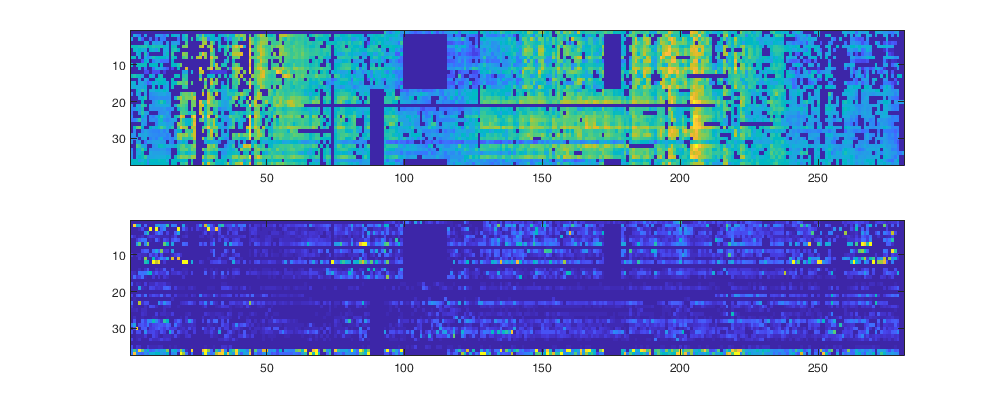

figure('position',[0 0 1000 400]); hold on;
subplot(2,1,1); imagesc(multi.M_m')
subplot(2,1,2); imagesc(sqrt(multi.M_var)'); caxis([0 .1])

Attribute block

multi.b = nan(size(multi.t));
for i_b=1:numel(data.block.date)
    if i_b==numel(data.block.date)
        multi.b(multi.t>=data.block.date(i_b) | multi.t<data.block.date(1)) = i_b;
    else
        multi.b(multi.t>=data.block.date(i_b) & multi.t<data.block.date(i_b+1)) = i_b;
    end
end
multi.B = repmat(multi.b,1,data.nrad);
data.day_b = multi.b;

## Trend

The trend is commputed as a polynomila of degree `poly_t_degree` in the time axis and `poly_t_degree` in space (2D). 

multi_poly_t_degree=0;
multi_poly_d_degree=1;

The trend is determined with a Generalized Linear Square regression (GLS), where the following linear problem is solved

$\beta^ˆ ={\left({\mathit{\mathbf{X}}}^{\top } C^{-1} \mathit{\mathbf{X}}\right)}^{-1} {\mathit{\mathbf{X}}}^{\top } C^{-1} \mathit{\mathbf{y}}$,

where $\beta^ˆ$ are the coefficient of the polynomes, $\mathbf{C}$ is the covariance matrix of the data $\mathbf{y}$. $\mathit{\mathbf{X}}$is the Vandermonde matrix for the time and coordinate of the data $\mathbf{y}$. In our case:

X = trend(multi.T,data.lat(multi.R),data.lon(multi.R),multi_poly_t_degree,multi_poly_d_degree);
C = diag(1+multi.M_var(:));
y = multi.M_m(:);

We can then create the forward function of the trend which given any location (time and coordinate) and polynomial coefficinet w return the value of the trend

multi.f_trend = @(t,lat,lon,beta) reshape(trend(t(:),lat(:),lon(:),multi_poly_t_degree,multi_poly_d_degree) * beta(:), size(t));

We will then compute the detrended value of the multi-night scale componenent

multi.M_mn=nan(size(multi.M_m));
multi.beta = nan(multi_poly_t_degree+ (multi_poly_d_degree)*2+1,numel(data.block.date));
idm_b=cell(numel(data.block.date),1);

We loop over all block...

for i_b=1:numel(data.block.date)

            ... first compute the block index....

    id = find(~multi.isnan & multi.B==i_b);

            .... and then, the trend coefficient $\beta^ˆ$

    multi.beta(:,i_b) = ((X(id,:)'*(C(id,id)\X(id,:)))\X(id,:)')*(C(id,id)\y(id)); % GLS

            Figure

    if false
        figure('position',[0 0 1000 400]); hold on;
        t_tmp = sort(unique(multi.T(id)));
        plot(t_tmp,multi.f_trend(t_tmp,mean(data.lat)*ones(numel(t_tmp),1),mean(data.lon)*ones(numel(t_tmp),1), multi.beta(:,i_b)),'-r')
        plot(multi.T(id),y(id),'.g')
        plot(multi.T(id),y(id),'.k')
    
        figure('position',[0 0 1000 400]);
        h=worldmap([floor(min(data.lat)) ceil(max(data.lat))], [floor(min(data.lon)) ceil(max(data.lon))]);
        setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
        [lat_tmp,lon_tmp]=meshgrid(floor(min(data.lat)):.2:ceil(max(data.lat)), floor(min(data.lon)):.2:ceil(max(data.lon)));
        S=multi.f_trend(mean(multi.T(id))*ones(size(lat_tmp)),lat_tmp,lon_tmp,multi.beta(:,i_b));
        surfm(lat_tmp,lon_tmp,S)
        plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
        [G,id]=findgroups(multi.R(id));
        scatterm(data.lat(id),data.lon(id),100,splitapply(@mean,y(id), G),'filled','MarkerEdgeColor','k');
        caxis([min(y(id)) max(y(id))])
    end

            Compute the de-trended value

    multi.M_mn(id) = multi.M_m(id)-multi.f_trend(multi.T(id),data.lat(multi.R(id)),data.lon(multi.R(id)),multi.beta(:,i_b));
end

Figure

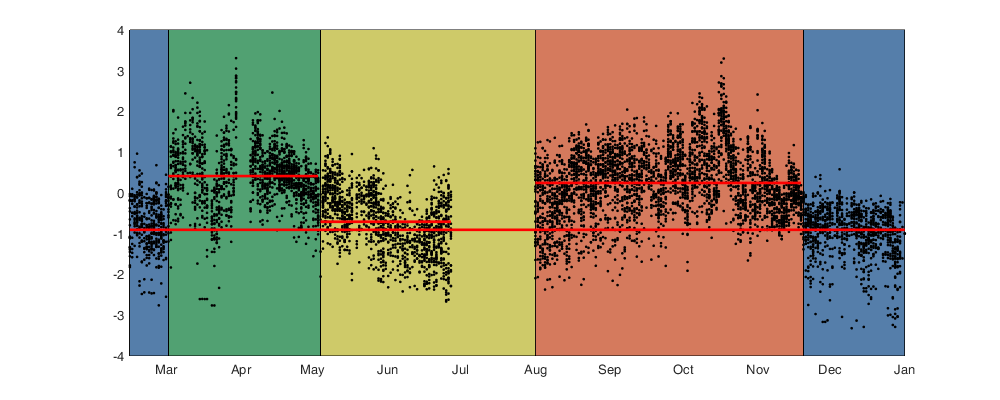

% col = [[0.0235    0.4824    0.2157];[0.7333    0.7059    0.1569];[0.7725    0.2549    0.1020];[0.0510    0.2784    0.5255]];

 figure('position',[0 0 1000 400]); hold on;
for i_b=1:numel(data.block.date)-1
    fill([data.block.date(i_b) data.block.date(i_b) data.block.date(i_b+1) data.block.date(i_b+1)],[4 -4 -4 4],data.block.col(i_b,:))
end
fill([min(data.day) min(data.day) data.block.date(1) data.block.date(1)],[4 -4 -4 4],data.block.col(4,:))
fill([data.block.date(end) data.block.date(end) max(data.day) max(data.day) ],[4 -4 -4 4],data.block.col(4,:))
plot(multi.T(:), y,'.k')
for i_b=1:numel(data.block.date)
    id = find(~multi.isnan & multi.B==i_b);
    t_tmp = sort(unique(multi.T(id)));
    plot(t_tmp, multi.f_trend(t_tmp,mean(data.lat(multi.R(id)))*ones(numel(t_tmp),1),mean(data.lon(multi.R(id)))*ones(numel(t_tmp),1), multi.beta(:,i_b)),'-r','Linewidth',2)
end
datetick('x'); ylim([-4 4]); axis tight;

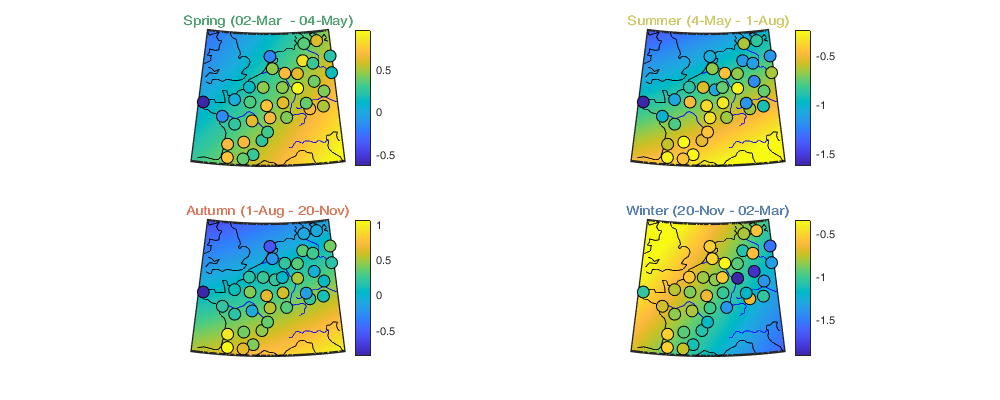

figure('position',[0 0 1000 400]); hold on; 
[LAT, LON] = meshgrid(floor(min(data.lat)):.1:ceil(max(data.lat)),floor(min(data.lon)):.1:ceil(max(data.lon)));
for i_b=1:numel(data.block.date)
    id = find(~multi.isnan & multi.B==i_b);
    subplot(2,2,i_b,'Color',data.block.col(i_b,:)); hold on; h=worldmap([floor(min(data.lat)) ceil(max(data.lat))], [floor(min(data.lon)) ceil(max(data.lon))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    surfm(LAT,LON,multi.f_trend(mean(multi.T(id))*ones(size(LAT)),LAT,LON,multi.beta(:,i_b))) 
    plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
    [G,tmp]=findgroups(multi.R(id));
    tmp2 = splitapply(@mean,multi.M(id),G);
    scatterm(data.lat(tmp),data.lon(tmp),80,tmp2,'filled','MarkerEdgeColor','k'); 
    title(data.block.date_str{i_b},'Color',data.block.col(i_b,:) ); caxis([min(tmp2) max(tmp2)])
    colorbar
end

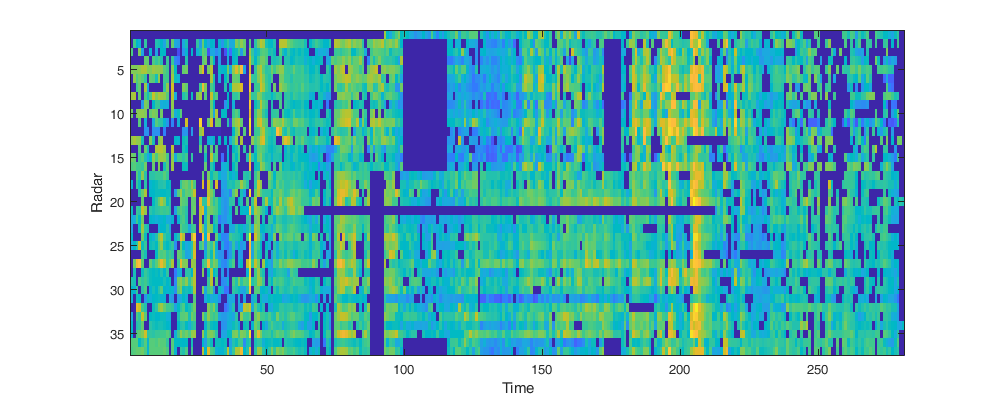

figure('position',[0 0 1000 400]); imagesc(multi.M_mn'); xlabel('Time'); ylabel('Radar')

## Covariance Multi

cov.d=[0 1 150 200 300 400 500 750 1000 2000];
cov.t=[0 1 2 3 4 5 10 20];
[cov.D,cov.T] = meshgrid(cov.d(1:end-1)+diff(cov.d)/2,cov.t(1:end-1));

cov.D_emp=nan(size(cov.D,1),size(cov.D,2),numel(data.block.date)-1);
cov.T_emp = cov.D_emp;
cov.emp_grid=nan(size(cov.D));

cov.nb=nan(numel(data.block.date)-1,1);
for i_b=1:numel(data.block.date)
    id = find(~multi.isnan & multi.B==i_b);
    cov.nb(i_b)=sum(id(:));
    Dtime=squareform(pdist(multi.T(id)));
    Ddist=squareform(pdist([data.lat(multi.R(id)) data.lon(multi.R(id))],@lldistkm));
    
    cov_emp = bsxfun(@times, multi.M_mn(id)', multi.M_mn(id));
    
    for i_t=1:numel(cov.t)-1
        for i_d=1:numel(cov.d)-1
            id = Dtime>=cov.t(i_t) & Dtime<cov.t(i_t+1) & Ddist>=cov.d(i_d) & Ddist<cov.d(i_d+1);
            cov.D_emp(i_t,i_d,i_b) = nanmean(Ddist(id));
            cov.T_emp(i_t,i_d,i_b) = nanmean(Dtime(id));
            cov.emp_grid(i_t,i_d,i_b) = nanmean( cov_emp(id) );
        end
    end
end

Figure

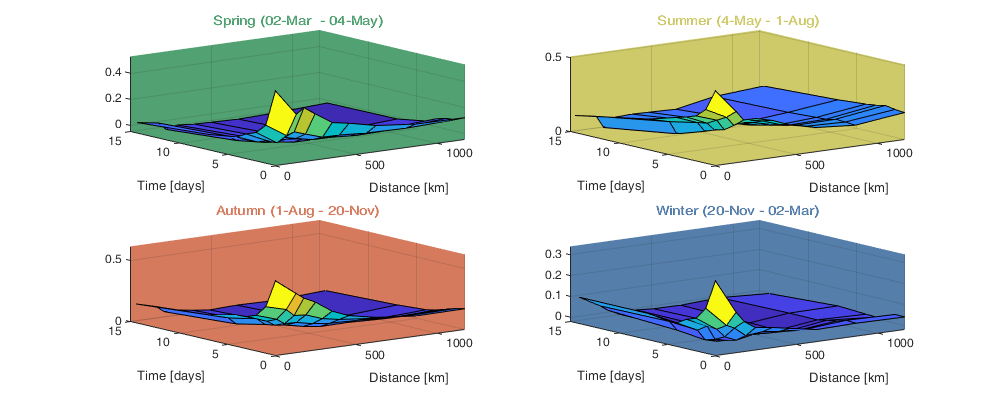

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,2,i_b); surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,2,i_b,'color',data.block.col(i_b,:)); 
end

## Covariance function fit

Gneiting_fit = @(parm,i_b) parm(1)*(cov.D_emp(:,:,i_b)==0 & cov.T_emp(:,:,i_b)==0) + parm(2)*(cov.D_emp(:,:,i_b)==0) + parm(3).*Gneiting(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),parm(4),parm(5),parm(6),parm(7),parm(8));

parm0 =[.05 0 .2 500 5 .2 .2 .2 ];
parm_min=[0.1 0.05 0 0.0001 0 0.6 0.6 0]';

for i_b=1:numel(data.block.date)
    id = find(~multi.isnan & multi.B==i_b);
    parm_max=[nancov(multi.M_mn(id)) nancov(multi.M_mn(id)) nancov(multi.M_mn(id)) 3000 10 1 1 1 ]';
    A = -[1 1 0 0 0 0 0 0];
    b = -0.9*(nancov(multi.M_mn(id))-max(cov.emp_grid(1,2,i_b),cov.emp_grid(2,1,i_b)));
    Aeq=[1 1 1 0 0 0 0 0];
    beq=nancov(multi.M_mn(id));
    rmse = @(parm) nansum(nansum( 1000*max(cov.emp_grid(:,:,i_b),0.01).*( (Gneiting_fit(parm,i_b) - cov.emp_grid(:,:,i_b)).^2 ) )); % 
    multi.cov.parm(:,i_b) = fmincon(rmse, parm0, A, b, Aeq, beq, parm_min, parm_max, [], optimoptions('fmincon','Display','off'));
    cov.parm0=multi.cov.parm(:,i_b);
end

Display parameters of covariance

fprintf(['nugget(0,0)\t nugget(0,:)\t var\t range distance[km]\t range time[day]\t shape distance (delta)\t shape time (gamma)\t separability (beta)\n%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f\n%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f\n%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f\n%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f'],multi.cov.parm)

nugget(0,0)	 nugget(0,:)	 var	 range distance[km]	 range time[day]	 shape distance (delta)	 shape time (gamma)	 separability (beta)
0.103		 0.079		 0.345	 844.685		 0.888			 0.677			 0.715			 0.808
0.134		 0.070		 0.305	 1716.697		 6.411			 0.600			 0.600			 1.000
0.100		 0.050		 0.464	 875.883		 2.523			 0.600			 0.600			 0.241
0.100		 0.065		 0.176	 462.520		 1.831			 0.600			 0.600			 0.000

Construct the covariance function as inline function.

multi.cov.Cn = @(D,T,parm) parm(1)*(D==0 & T==0) + parm(2)*(D==0) + parm(3).*Gneiting(D,T,parm(4),parm(5),parm(6),parm(7),parm(8));
multi.cov.C = @(D,T,parm) parm(3).*Gneiting(D,T,parm(4),parm(5),parm(6),parm(7),parm(8));

 Illustration of the fitted covariance function

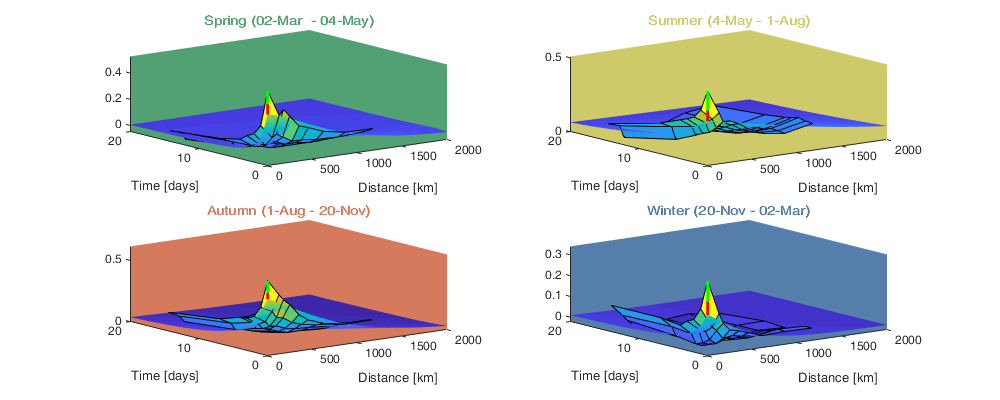

[tmpD,tmpT] = meshgrid(cov.d(1):1:cov.d(end),cov.t(1):0.1:cov.t(end));
figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,2,i_b); hold on
    s=surf(tmpD,tmpT,multi.cov.Cn(tmpD, tmpT,multi.cov.parm(:,i_b))); s.EdgeColor='none';
    surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); view(3);
    plot3([0 0],[0 0],[multi.cov.parm(3,i_b) sum(multi.cov.parm(2:3,i_b))],'r', 'linewidth',2)
    plot3([0 0],[0 0],[sum(multi.cov.parm(2:3,i_b)) sum(multi.cov.parm(1:3,i_b))],'g', 'linewidth',2)
    subplot(2,2,i_b,'color',data.block.col(i_b,:)); 
end

Clear all un-necessary variable

%clear C cov* Ddist Dtime G Gneiting_fit h i* L* parm* rmse s tmp* X y ans

## Intra-night scale

At the intra-night scale, we model the the fluctuation around the multi-night scale

% save memory intra.I = data.denst-multi.M(data.day_id,:,:);
intra.I_m = nanmean(data.denst-multi.M(data.day_id,:,:),3);
intra.I_var = nanvar(data.denst-multi.M(data.day_id,:,:),[],3);
intra.I_var(intra.I_m<-1.5)=nan;
intra.I_m(intra.I_m<-1.5)=nan;
intra_isnan = isnan(intra.I_m);

Block decomposition

intra.b = nan(size(data.time));
for i_b=1:numel(data.block.date)
    if i_b==numel(data.block.date)
        intra.b(datenum(data.time)>=data.block.date(4) | datenum(data.time)<data.block.date(1)) = i_b;
    else
        intra.b(datenum(data.time)>=data.block.date(i_b) & datenum(data.time)<data.block.date(i_b+1)) = i_b;
    end
end
intra.b = uint8(intra.b);
intra_B = repmat(intra.b,1,data.nrad);

The most important trend at the intra-night scale is along the the night. We use a polynomial function to account for this smooth variation


$$\iota \left(t,\mathit{\mathbf{s}}\right)=\sum_{i=i}^8 a_i \textrm{NNT}\left(t,\mathit{\mathbf{s}}\right)$$


intra_poly_degree=8;
X=bsxfun(@power,data.NNT(:),intra_poly_degree:-1:0);
C=spdiags(1+intra.I_var(:), 0, numel(intra.I_var), numel(intra.I_var));
intra.f_trend = @(t,beta) reshape(bsxfun(@power,t(:),intra_poly_degree:-1:0) * beta(:),size(t));

We will then compute the detrended value of the multi-night scale componenent

I_mn_tmp=nan(size(intra.I_m));
intra.beta = nan(intra_poly_degree+1,numel(data.block.date));

We loop over all block...

for i_b=1:numel(data.block.date)
    id = intra_B==i_b & ~intra_isnan;
    intra.beta(:,i_b) = ((X(id,:)'*(C(id,id)\X(id,:)))\X(id,:)')*(C(id,id)\intra.I_m(id)); % GLS
    I_mn_tmp(id) = intra.I_m(id) - intra.f_trend(data.NNT(id),intra.beta(:,i_b));
end

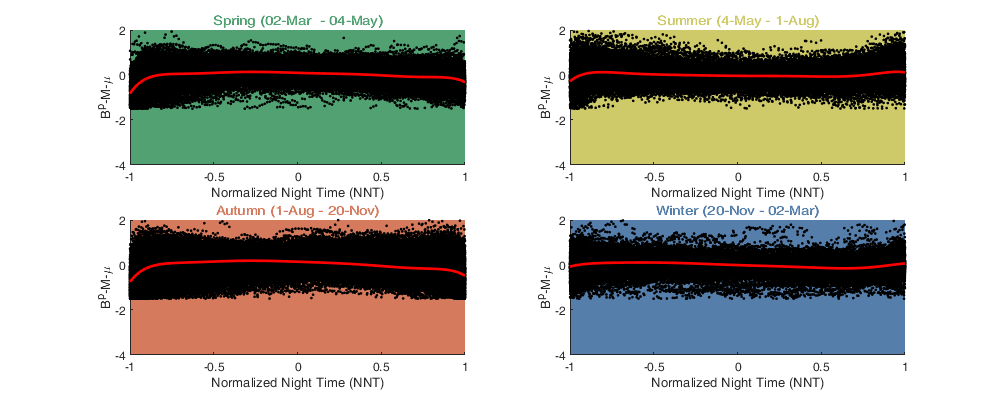

NNT_axis=-1:.01:1;
figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    id = intra_B==i_b & ~intra_isnan;
    subplot(2,2,i_b,'color',data.block.col(i_b,:)); hold on
    plot(data.NNT(id),intra.I_m(id),'.k');
    plot(NNT_axis, intra.f_trend(NNT_axis, intra.beta(:,i_b)),'-r','linewidth',2);
    title(data.block.date_str{i_b},'color',data.block.col(i_b,:)); 
    subplot(2,2,i_b,'color',data.block.col(i_b,:)); 
    xlabel('Normalized Night Time (NNT)'); ylabel('B^p-M-\mu'); ylim([-4 2]); xlim([-1 1])
end

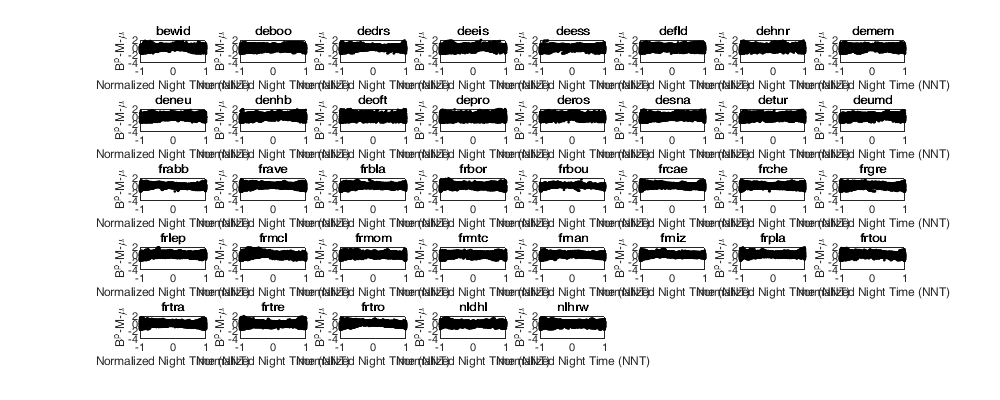

figure('position',[0 0 1000 400]);
for i_r = 1:data.nrad
    subplot(5,8,i_r); 
    plot(data.NNT(:,i_r),intra.I_m(:,i_r),'.k');
    title(data.name(i_r)); 
    xlabel('Normalized Night Time (NNT)'); ylabel('B^p-M-\mu'); ylim([-4 2]); xlim([-1 1]) 
end

In addition to present a trend of the mean, the intra-night components also contains a non-stationarity of variance along the night (see figure below). We fit another polynomial function to normalize the variance


$$\sigma_I \left(t,\mathit{\mathbf{s}}\right)=\sum_{i=i}^{10} b_i \textrm{NNT}\left(t,\mathit{\mathbf{s}}\right)$$


intra_poly_degree_v=6;
X=bsxfun(@power,data.NNT(:),intra_poly_degree_v:-1:0);
intra.f_trend_v = @(t,beta_v) reshape(bsxfun(@power,t(:),intra_poly_degree_v:-1:0) * beta_v(:),size(t));

We will then compute the detrended value of the multi-night scale componenent

intra_I_var_n=nan(size(intra.I_m));
intra.beta_v = nan(intra_poly_degree_v+1,numel(data.block.date));

We loop over all block...

for i_b=1:numel(data.block.date)
    id = intra_B==i_b & ~intra_isnan;
    intra.beta_v(:,i_b) = (X(id,:)'*X(id,:))\(X(id,:)'*I_mn_tmp(id).^2);
    intra_I_var_n(id) = intra.f_trend_v(data.NNT(id),intra.beta_v(:,i_b));
end

Illustration

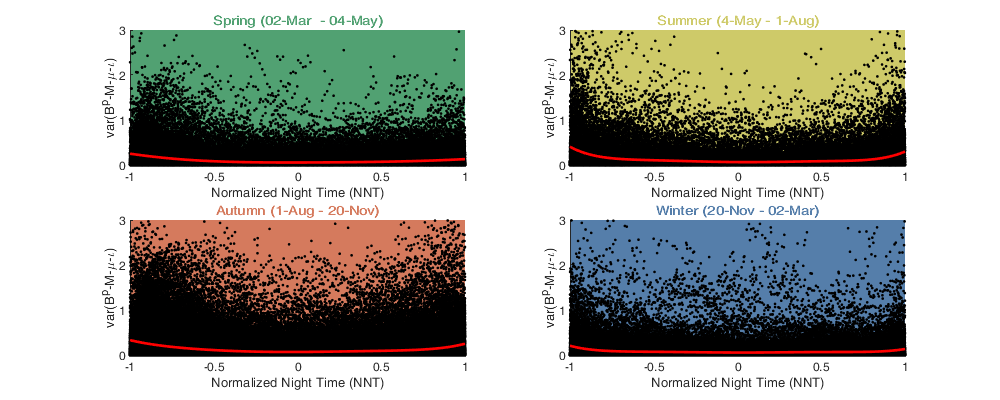

NNT_axis=-1:.01:1;
figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    id = intra_B==i_b & ~intra_isnan;
    subplot(2,2,i_b,'color',data.block.col(i_b,:)); hold on
    plot(data.NNT(id),I_mn_tmp(id).^2,'.k');
    plot(NNT_axis, intra.f_trend_v(NNT_axis,intra.beta_v(:,i_b)),'-r','linewidth',2);
    title(data.block.date_str{i_b},'color',data.block.col(i_b,:)); 
    subplot(2,2,i_b,'color',data.block.col(i_b,:)); 
    xlabel('Normalized Night Time (NNT)'); ylabel('var(B^p-M-\mu-\iota)');ylim([0 3]); xlim([-1 1])
end

Finally, combining the polynomial of the curve and the correction for variance, we find the de-trended intra-night scale $I$

intra.I_mn = I_mn_tmp(~intra_isnan) ./ sqrt(intra_I_var_n(~intra_isnan));
intra.I_varn = intra.I_var(~intra_isnan) ./ intra_I_var_n(~intra_isnan);

Check the histogram

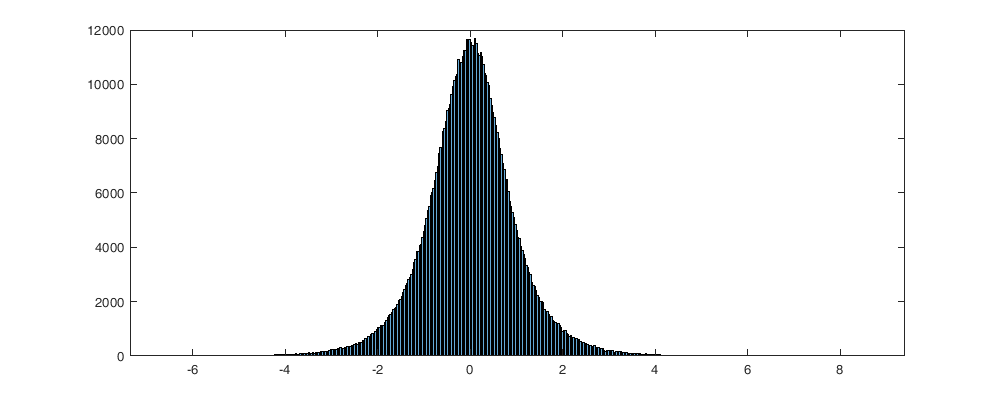

figure('position',[0 0 1000 400]); histogram(intra.I_mn);

% clear C y i_* X id I_mn_tmp intra_I_var_n

## 4.2 Covariance function of $I\left(t,\mathit{\mathbf{s}}\right)$

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

Ddist_sm = squareform(pdist([data.lat data.lon], @lldistkm));
tmp=repmat(1:data.nrad,data.ntime,1);
intra_radar = tmp(~intra_isnan);
tmp=repmat(data.day(data.day_id),1,data.nrad);
intra_day = tmp(~intra_isnan);
tmp=repmat(datenum(data.time),1,data.nrad);
intra_time = tmp(~intra_isnan);

cov.d=[0 1 100 150 200 250 300 600 1000];
cov.t=[0 .01 .02 .05 .07 .1 .2];
[cov.D,cov.T]=meshgrid(cov.d(1:end-1)+diff(cov.d)/2,cov.t(1:end-1)+diff(cov.t)/2);
cov.D_emp=nan(size(cov.D,1),size(cov.D,2),numel(data.block.date)); 
cov.T_emp=nan(size(cov.D_emp));
cov.emp_grid=nan(size(cov.D_emp));

for i_b=1:numel(data.block.date)

    D = nan(1000000000,2);
    Did = zeros(1000000000,2,'uint32');
    i=0;
    for i_t=data.day(data.day_b==i_b)'
        id = find(intra_day==i_t);
        tmp1 = [reshape(Ddist_sm(intra_radar(id),intra_radar(id)),[],1) reshape(squareform(pdist(intra_time(id))),[],1)];
        tmp2 = [uint32(repmat(id,numel(id),1)) uint32(repelem(id,numel(id)))];
        
        B = tril(ones(numel(id)));
        id2=B(:)==1 & tmp1(:,1)<cov.d(end) & tmp1(:,2)<cov.t(end);
        D(i+(1:sum(id2)),:)=tmp1(id2,:);
        Did(i+(1:sum(id2)),:)=tmp2(id2,:);
        i=i+sum(id2);
    end
    D=D(1:i,:);
    Did=Did(1:i,:);

    
    for i_d=1:numel(cov.d)-1
        id1 = find(D(:,1)>=cov.d(i_d) & D(:,1)<cov.d(i_d+1));
        for i_t=1:numel(cov.t)-1
            id2 = id1(D(id1,2)>=cov.t(i_t) & D(id1,2)<cov.t(i_t+1));
            cov.emp_grid(i_t,i_d,i_b)= mean(intra.I_mn(Did(id2,1)) .* intra.I_mn(Did(id2,2)));
            cov.D_emp(i_t,i_d,i_b) = nanmean(D(id2,1));
            cov.T_emp(i_t,i_d,i_b) = nanmean(D(id2,2));
        end
    end
end

Figure

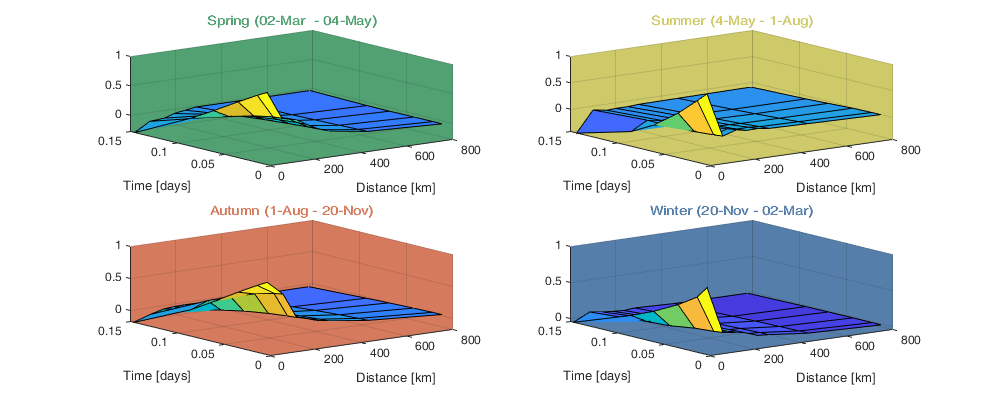

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,2,i_b); surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,2,i_b,'color',data.block.col(i_b,:)); 
end

Gneiting_fit = @(parm,i_b) parm(1)*(cov.D_emp(:,:,i_b)==0 & cov.T_emp(:,:,i_b)==0) + parm(2)*(cov.D_emp(:,:,i_b)==0) + parm(3).*Gneiting(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),parm(4),parm(5),parm(6),parm(7), parm(8));

parm0 =[.05 .05 .8 500 5 .2 .2 .2 ];
parm_min=[.05 .05 0 0.0001 0 0.6 0.6 0 ]';

for i_b=1:numel(data.block.date)
    parm_max = [cov.emp_grid(1,1,i_b) cov.emp_grid(1,1,i_b) cov.emp_grid(1,1,i_b) 3000 10 1 1 1 ]';
    A = -[1 1 0 0 0 0 0 0];
    b = -0.9*(cov.emp_grid(1,1,i_b)-max(cov.emp_grid(1,2,i_b)));
    Aeq=[1 1 1 0 0 0 0 0];
    beq=cov.emp_grid(1,1,i_b);
    rmse = @(parm) nansum(nansum( ( 1000*max(cov.emp_grid(:,:,i_b),0.01) .* (Gneiting_fit(parm,i_b) - cov.emp_grid(:,:,i_b)).^2 ) ));
    intra.cov.parm(:,i_b) = fmincon(rmse,parm0,A, b, Aeq, beq,parm_min,parm_max,[],optimoptions('fmincon','Display','off'));
    parm0=intra.cov.parm(:,i_b);
end

Display parameters of covariance

fprintf(['nugget(0,0)\t nugget(0,:)\t var\t range distance[km]\t range time[day]\t shape distance (delta)\t shape time (gamma)\t separability (beta)\n' ...
    '%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f\n' ...
    '%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f\n' ...
    '%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f\n' ...
    '%.3f\t\t %.3f\t\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f'],intra.cov.parm)

nugget(0,0)	 nugget(0,:)	 var	 range distance[km]	 range time[day]	 shape distance (delta)	 shape time (gamma)	 separability (beta)
0.095		 0.338		 0.526	 252.078		 0.051			 1.000			 1.000			 1.000
0.138		 0.626		 0.162	 630.667		 0.016			 1.000			 0.885			 1.000
0.077		 0.126		 0.762	 198.581		 0.066			 1.000			 0.971			 0.685
0.134		 0.458		 0.304	 270.859		 0.031			 1.000			 0.931			 1.000

Construct the covariance function as inline function.

intra.cov.Cn = @(D,T,parm) parm(1)*(D==0 & T==0) + parm(2)*(D==0) + parm(3).*Gneiting(D,T,parm(4),parm(5),parm(6),parm(7),parm(8));
intra.cov.C = @(D,T,parm) parm(3).*Gneiting(D,T,parm(4),parm(5),parm(6),parm(7),parm(8));

Figure

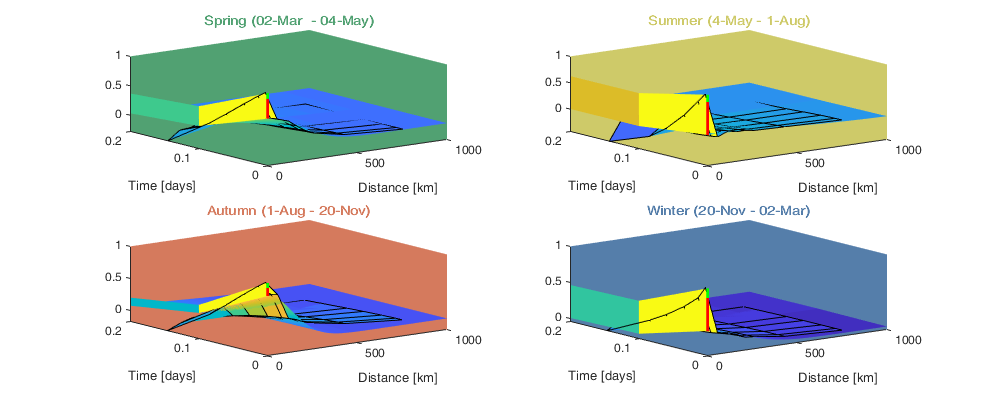

[tmpD,tmpT] = meshgrid(cov.d(1):1:cov.d(end),cov.t(1):0.1:cov.t(end));

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,2,i_b); hold on
    s=surf(tmpD,tmpT,intra.cov.Cn(tmpD, tmpT,intra.cov.parm(:,i_b))); s.EdgeColor='none';
    surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); view(3);
    plot3([0 0],[0 0],[intra.cov.parm(3,i_b) sum(intra.cov.parm(2:3,i_b))],'r', 'linewidth',2)
    plot3([0 0],[0 0],[sum(intra.cov.parm(2:3,i_b)) sum(intra.cov.parm(1:3,i_b))],'g', 'linewidth',2)
    subplot(2,2,i_b,'color',data.block.col(i_b,:)); 
end

## 5. Save

Save the parameters of the model. 

save('data/Density_inference.mat','data','multi','intra','trans','-v7.3')
% load('data/Density_inference.mat')
% writetable(data,'data/Density_data.csv')